clear all;
filelist = ["data_04-Mar-2025_10.mat", 
"data_21-Mar-2025_10 motor0 19 to 31 rads.mat",
"data_21-Mar-2025_20 motor0 1v.mat",
"data_21-Mar-2025_20 motor0 31 to 40 rads 1.5v.mat"];
Ts = 1/500;
do_plots = false;
tableofData = [];
idObj=false;
for exp_id = 1:4
    file = "lab3/data/motor0/" + filelist(exp_id);
    load(file,"data");
    if do_plots
        smartPlotEncVoltage(data,filelist(exp_id),false);
    end
    
    fs=500;
    ts = 1/fs;
    
    motorID = 0;
    
    voltages_A = [1 1 1 1.5];
    voltage_A = voltages_A(exp_id);
    time = data(1,:);
    y = data(2+motorID,:)*pi/2048;
    u = data(4+motorID,:);
    % sweepanalysis assumes that the u has Amplitude 1
    om = data(6,:);
    
    
    slices = sliceTimeSeries(time,om);
    
    
    % wrong_exp = [ 0 5.5 13 17.5 18 20];
    
    maskOpts = detectImportOptions("lab3/data/motor0/experiment_mask_"+exp_id+".csv");
    mask = readtable("lab3/data/motor0/experiment_mask_"+exp_id+".csv",maskOpts);
    
    
    % for i = 2:2
    for i = 1:size(slices,2)
        omega = slices{i}.f;
        % k = find(wrong_exp==omega);
    if mask.enable(i) % it's one of the wrong experiments
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+mask.t_start(i));
        t_end_idx = time2index(focus.t_end-mask.t_end(i));
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        y_focus= y(t_start_idx:t_end_idx);
        u_focus= u(t_start_idx:t_end_idx);
        
        
        % [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,data,to_merge);
        

        if idObj == false
            [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,false,false);
            idObj = true;
        else
            [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,dataDD,true);
        end

        

    else
        continue
    end
    end
   

end



% Details about Estimation Data    
 % Import   dataDD                 
                                   
% Transfer function estimation     
 Options = tfestOptions;           
 Options.Display = 'on';           
 Options.EnforceStability = true;  
                                   
 tf2 = tfest(dataDD, 1, 0, Options);


tf2 =
 
  From input "u1" to output "y1":
    -0.9627
  -----------
  s + 0.01485
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                                                                          
Estimated using TFEST on time domain data "dataDD".                                                              
Fit to estimation data: [61.79 60.75 60.56 57.64 58.64 58.32 55.99 53.37 52.2 54.57....% (stability enforced)    
FPE: 0.000677, MSE: [0.006132 0.004444 0.003716 0.003838 0.002934 0.002654 0.002702 0.002712 0.002448 0.001922...
 


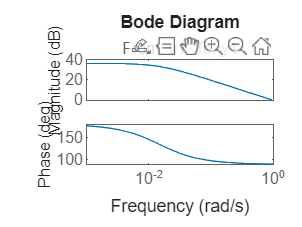

bodeplot(tf2)


function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end